# Gauss-Seidel for Tensor-Regression Video Deblur

clear;clc;close all;
addpath('../deblurring')
addpath('../tproduct toolbox 2.0 (transform)/')

%import data
load mri;                               %loads mri video as order-4 tensor
X = squeeze(double(D));                 %gets rid of dimension 1 mode
X = X(:,:,1:12);                        %takes only first 12 frames                       
[m1,n1,p] = size(X);                    %m1 = 128, n1 = 128, p = 12

%blur
h = fspecial('gaussian',[5,5],2);       %builds a Gaussian low-pass filter
[m2,n2] = size(h);                      %size 5x5 (m2=5, n2 = 5)

m = m1+m2-1;                            %m = n = 132 (gives room for the 
n = n1+n2-1;                            %  convolutions at the edges)

Y  = zeros(m1,n1,p);                    %build blurry video tensor
for i = 1:p
    Y(:,:,i) = imfilter(X(:,:,i),h,'symmetric');%conv2(X(:,:,i),h,'same');
end

s = floor((m2-1)/2);                    %calculates number of edge pad pixels
t = floor((n2-1)/2);


Y_pad = zeros(m,n,p);                   %pads and reorders modes for regression
Y_pad_reorder = zeros(n,p,m);
for k = 1:p
    %y_pad(:,:,k) = padarray(y(:,:,k),[s,t],'symmetric','both');
    Y_pad(:,:,k) = padarray(Y(:,:,k),[s,t],'replicate','both');
    for i = 1:m
        for j = 1:n
            Y_pad_reorder(j,k,i) = Y_pad(i,j,k);
        end
    end
end

%builds tensor representation of filter
A = conv2tensor([m1,n1],h); % size: n x n1 x m

### Initializing with Zero Tensor

%solve system, initializing at 0 tensor
%builds initial iterate tensor
X0 = zeros(n1,p,m);

%apply tensor regression technique
num_its = 100000;
X_true = zeros(size(X0));
for i = 1:size(X,2)
    X_true(:,:,i) = X(:,i,:);
end
X_ln = tprod(tpinv(A),Y_pad_reorder);
[Z,errs,~,ln_errs,~] = tRGS_err(A,Y_pad_reorder,X0,num_its,X_true,X_ln);

%remove padding
Z = Z(:,:,1:m1);

%permute modes back to original video shape
Z = permute(Z,[3,1,2]); % n1 x p x m1 -> m1 x n1 x p

%remove ringing artifacts
Z(Z<0) = 0;

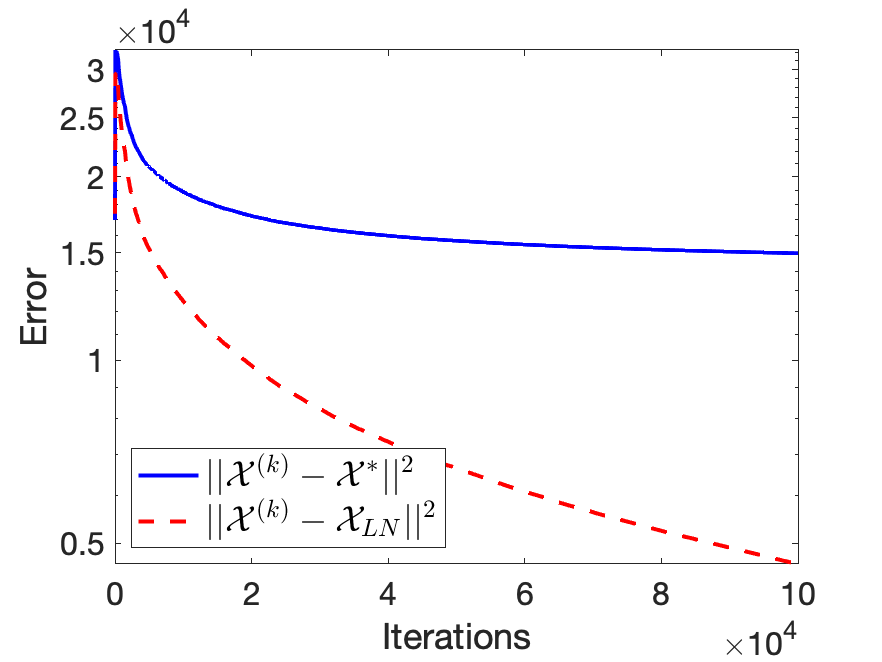

%plot errors vs iterations
figure(1);
semilogy(0:num_its,errs,'b-',0:num_its,ln_errs,'r--','LineWidth',2)
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||^2$','FontSize',18,'Interpreter','latex','Location','southwest')
savefig('figs/tRGS_deblurring_error_zeroinitialization.fig')
saveas(gcf,'figs/tRGS_deblurring_error_zeroinitialization.png')

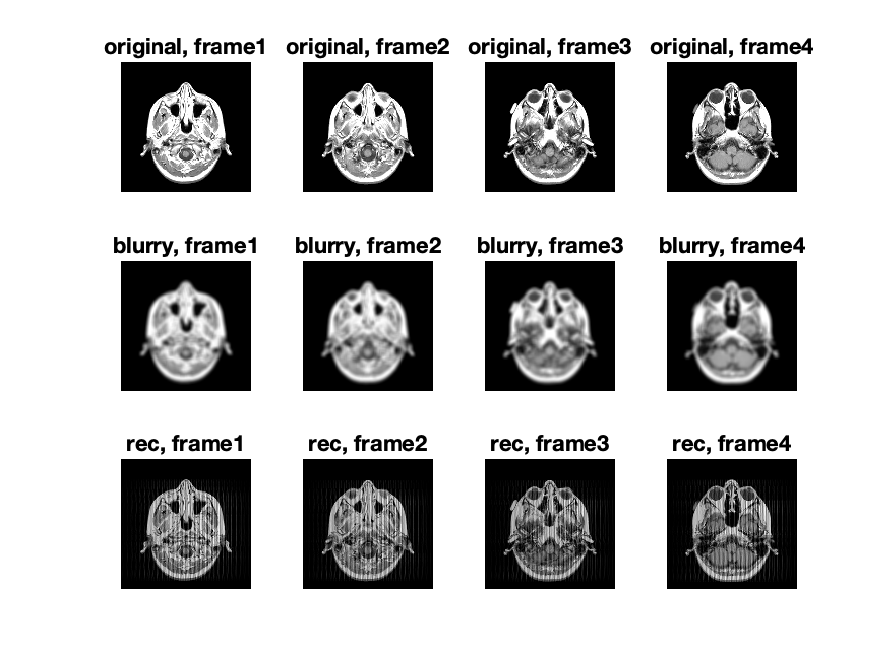

figure(2);
it = 4;
for i = 1:it
    subplot(3,it,i)
    imagesc(X(:,:,i));axis image off;colormap gray
    title(sprintf('original, frame%d',i))

    subplot(3,it,i+it)
    imagesc(Y(:,:,i));axis image off;colormap gray
    title(sprintf('blurry, frame%d',i))
    
    subplot(3,it,i+2*it)
    imagesc(Z(:,:,i));axis image off;colormap gray
    title(sprintf('rec, frame%d',i))    
end

savefig('figs/tRGS_deblurring_zeroinitialization.fig')
saveas(gcf,'figs/tRGS_deblurring_zeroinitialization.png')

It looks like we might be converging to the least-norm solution, so to avoid this, let's try initializing with the blurry image!

### Initializing with Noisy Image

%solve system, initializing at 0 tensor
%builds initial iterate tensor from noisy image tensor
X0 = zeros([n1,p,m]);
X0(:,:,1:size(Y,2)) = permute(Y,[2,3,1]);

%apply tensor regression technique
X_true = zeros(size(X0));
for i = 1:size(X,2)
    X_true(:,:,i) = X(:,i,:);
end
X_ln = tprod(tpinv(A),Y_pad_reorder);
[Z,errs,~,ln_errs,~] = tRGS_err(A,Y_pad_reorder,X0,num_its,X_true,X_ln);

%remove padding
Z = Z(:,:,1:m1);

%permute modes back to original video shape
Z = permute(Z,[3,1,2]); % n1 x p x m1 -> m1 x n1 x p

%remove ringing artifacts
Z(Z<0) = 0;

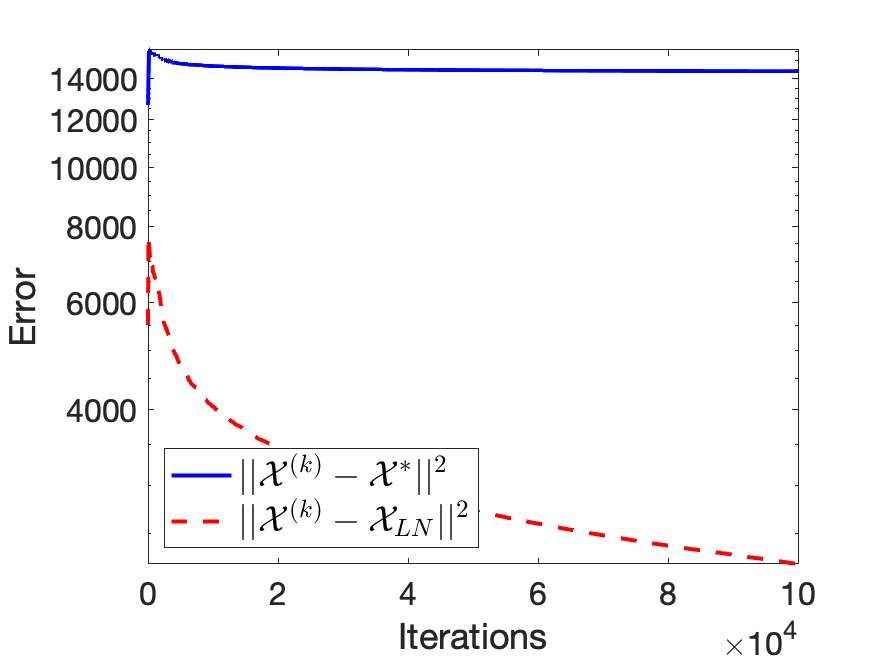

%plot errors vs iterations
figure(3);
semilogy(0:num_its,errs,'b-',0:num_its,ln_errs,'r--','LineWidth',2)
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||^2$','FontSize',18,'Interpreter','latex','Location','southwest')
savefig('figs/tRGS_deblurring_error_blurryinitialization.fig')
saveas(gcf,'figs/tRGS_deblurring_error_blurryinitialization.png')

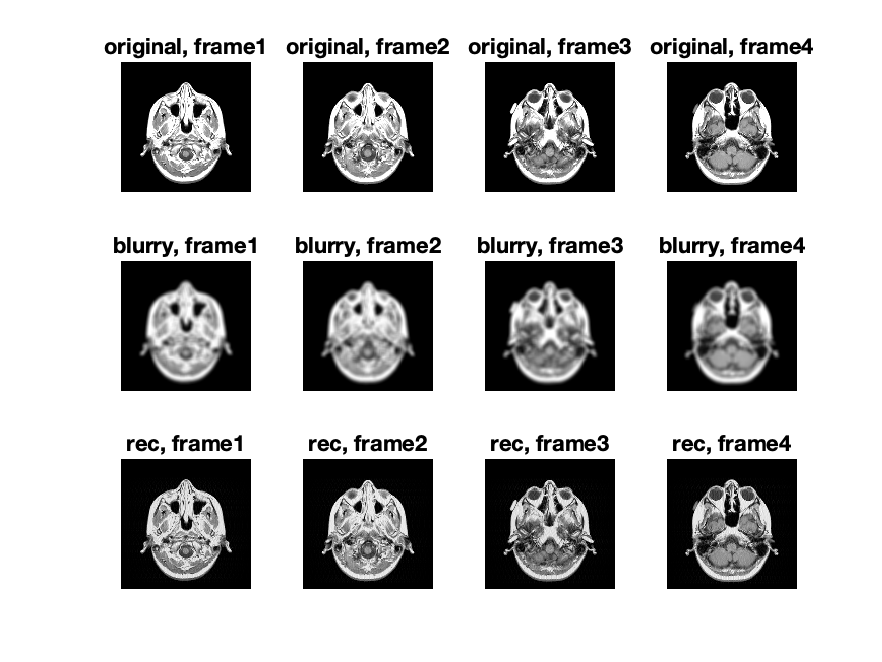

figure(4);
it = 4;
for i = 1:it
    subplot(3,it,i)
    imagesc(X(:,:,i));axis image off;colormap gray
    title(sprintf('original, frame%d',i))

    subplot(3,it,i+it)
    imagesc(Y(:,:,i));axis image off;colormap gray
    title(sprintf('blurry, frame%d',i))
    
    subplot(3,it,i+2*it)
    imagesc(Z(:,:,i));axis image off;colormap gray
    title(sprintf('rec, frame%d',i))    
end

savefig('figs/tRGS_deblurring_blurryinitialization.fig')
saveas(gcf,'figs/tRGS_deblurring_blurryinitialization.png')

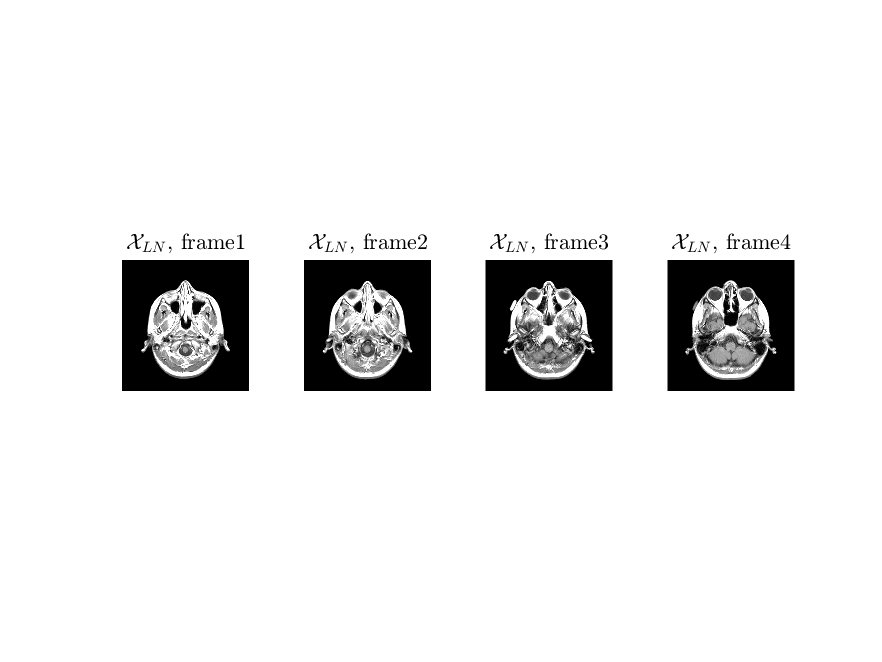

figure(5);
it = 4;
X_LN = permute(X_ln,[1,3,2]);
for i = 1:it
    subplot(3,it,i+it)
    imagesc(permute(X_LN(:,:,i),[2,1,3]));axis image off;colormap gray
    title(['$\mathcal{X}_{LN}$',sprintf(', frame%d',i)],'Interpreter','latex')
end